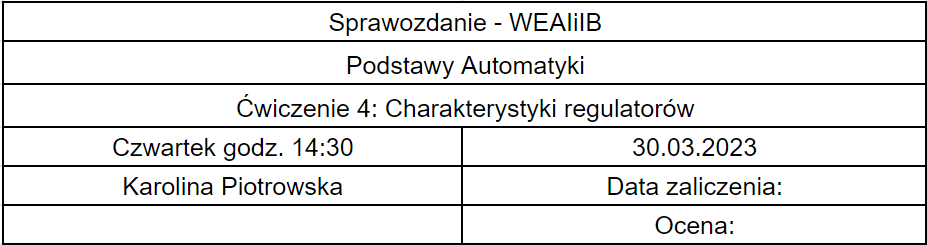

## Cel ćwiczenia

Ćwiczenie miało na celu zapoznanie się z charakterystykami czasowymi i częstotliwościowymi podstawowych typów regulatorów ciągłch.

## Wstęp teoretyczny

Podczas ćwiczenia rozważaliśmy następujące regulatory:

- Regulator PI o transmitancji


$$G(s) = k(1 + \frac{1}{T_{i}s})$$


- Regulator PD o transmitancji


$$G(s) = k(1 + \frac{T_{d}s}{Ts + 1})$$


- Regulator PID o transmitancji


$$G(s) = k(1 + \frac{1}{T_{i}s} + \frac{T_{d}s}{Ts+1})$$


## Przebieg laboratorium

### Regulator PI

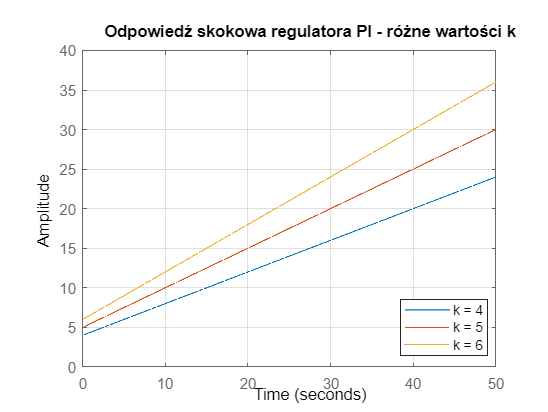

%--------------- różne k
k1 = 4;
k2 = 5;
k3 = 6;
Ti = 10;

licz1 = [k1*Ti k1];
licz2 = [k2*Ti k2];
licz3 = [k3*Ti k3];
mian = [Ti 0];

figure();
step(licz1, mian)
hold on
step(licz2, mian)
step(licz3, mian)
hold off
grid on
title('Odpowiedź skokowa regulatora PI - różne wartości k')
legend('k = 4', 'k = 5', 'k = 6')
legend('Location', 'best')

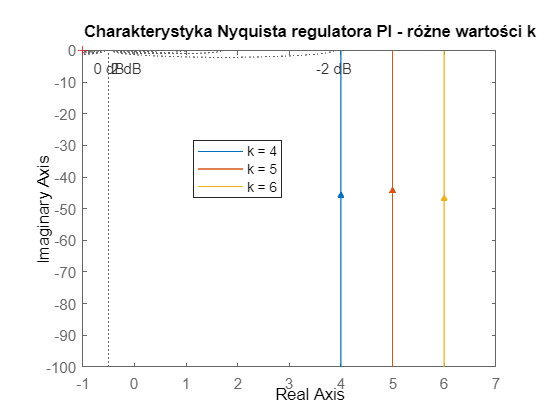


figure();
G1 = tf(licz1, mian);
G2 = tf(licz2, mian);
G3 = tf(licz3, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions)
hold on
nyquist(G2, plotoptions)
nyquist(G3, plotoptions)
hold off
grid on
title('Charakterystyka Nyquista regulatora PI - różne wartości k')
legend('k = 4', 'k = 5', 'k = 6')
legend('Location', 'best')

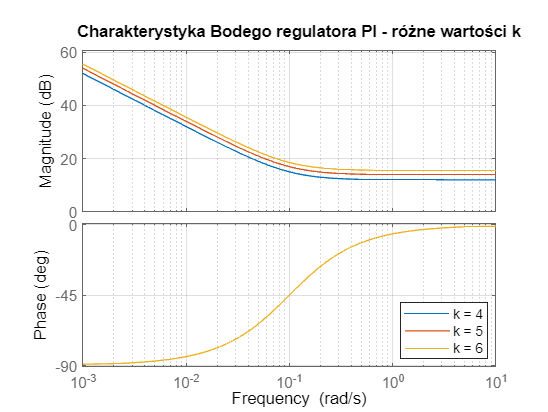


figure()
bode(licz1, mian)
hold on
bode(licz2, mian)
bode(licz3, mian)
hold off
grid on
title('Charakterystyka Bodego regulatora PI - różne wartości k')
legend('k = 4', 'k = 5', 'k = 6')
legend('Location', 'best')

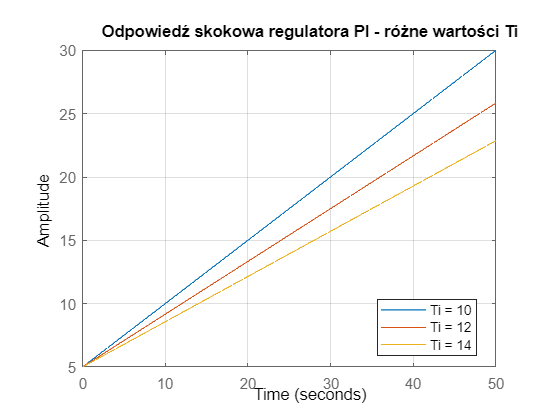


%-------------- różne Ti
k = 5;
Ti1 = 10;
Ti2 = 12;
Ti3 = 14;

licz1 = [k*Ti1 k];
licz2 = [k*Ti2 k];
licz3 = [k*Ti3 k];
mian1 = [Ti1 0];
mian2 = [Ti2 0];
mian3 = [Ti3 0];

figure();
step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
grid on
title('Odpowiedź skokowa regulatora PI - różne wartości Ti')
legend('Ti = 10', 'Ti = 12', 'Ti = 14')
legend('Location', 'best')

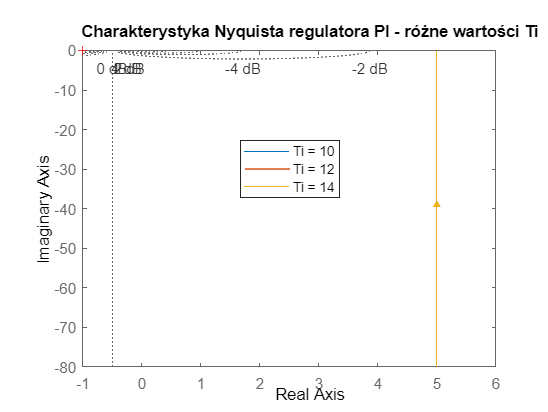


figure();
G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions)
hold on
nyquist(G2, plotoptions)
nyquist(G3, plotoptions)
hold off
grid on
title('Charakterystyka Nyquista regulatora PI - różne wartości Ti')
legend('Ti = 10', 'Ti = 12', 'Ti = 14')
legend('Location', 'best')

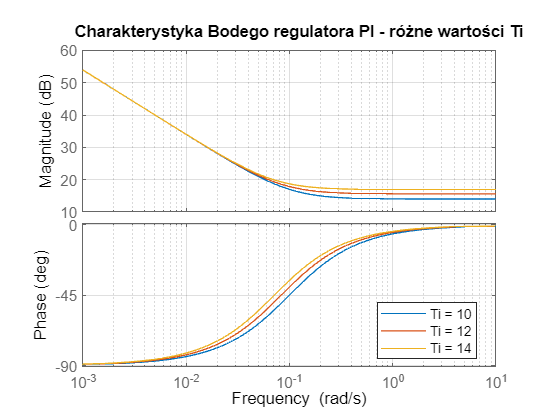


figure()
bode(licz1, mian)
hold on
bode(licz2, mian)
bode(licz3, mian)
hold off
grid on
title('Charakterystyka Bodego regulatora PI - różne wartości Ti')
legend('Ti = 10', 'Ti = 12', 'Ti = 14')
legend('Location', 'best')

### Regulator PD

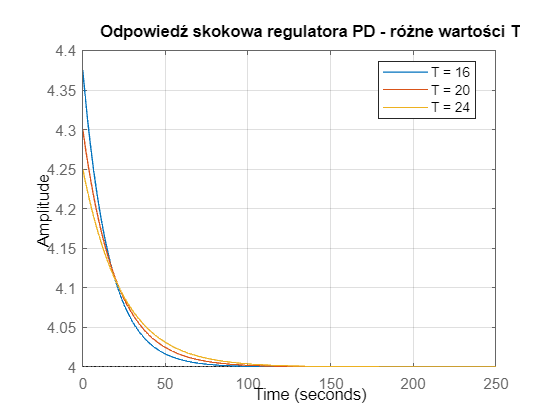

%-------------- różne wartości T
k = 4;
Td = 1.5;
T1 = 16;
T2 = 20;
T3 = 24;

licz1 = [k*T1 + k*Td k];
licz2 = [k*T2 + k*Td k];
licz3 = [k*T3 + k*Td k];
mian1 = [T1 1];
mian2 = [T2 1];
mian3 = [T3 1];

figure();
step(licz1, mian1)
hold on
step(licz2, mian2)
step(licz3, mian3)
hold off
grid on
title('Odpowiedź skokowa regulatora PD - różne wartości T')
legend('T = 16', 'T = 20', 'T = 24')
legend('Location', 'best')

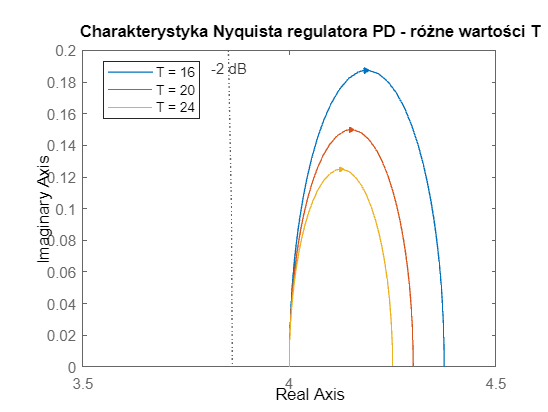


figure();
G1 = tf(licz1, mian1);
G2 = tf(licz2, mian2);
G3 = tf(licz3, mian3);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions)
hold on
nyquist(G2, plotoptions)
nyquist(G3, plotoptions)
hold off
grid on
title('Charakterystyka Nyquista regulatora PD - różne wartości T')
legend('T = 16', 'T = 20', 'T = 24')
legend('Location', 'best')
xlim([3.5 4.5])

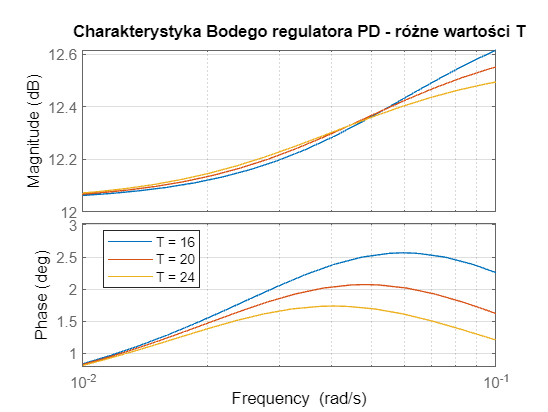


figure()
bode(licz1, mian1)
hold on
bode(licz2, mian2)
bode(licz3, mian3)
hold off
grid on
title('Charakterystyka Bodego regulatora PD - różne wartości T')
legend('T = 16', 'T = 20', 'T = 24')
legend('Location', 'best')

### Regulator PID

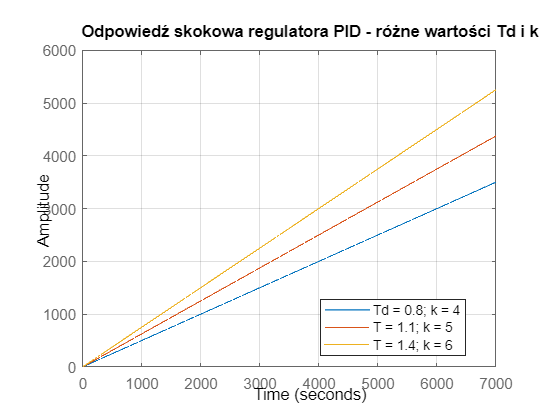

k1 = 4;
k2 = 5;
k3 = 6;
Td1 = 0.8;
Td2 = 1.1;
Td3 = 1.4;
T = 15;
Ti = 8;

licz1 = [k1*Ti*(T+Td1) k1*(T+Td1) k1];
licz2 = [k2*Ti*(T+Td2) k2*(T+Td2) k2];
licz3 = [k3*Ti*(T+Td3) k3*(T+Td3) k3];
mian = [Ti*T Ti 0];

figure();
step(licz1, mian)
hold on
step(licz2, mian)
step(licz3, mian)
hold off
grid on
title('Odpowiedź skokowa regulatora PID - różne wartości Td i k')
legend('Td = 0.8; k = 4', 'T = 1.1; k = 5', 'T = 1.4; k = 6')
legend('Location', 'best')

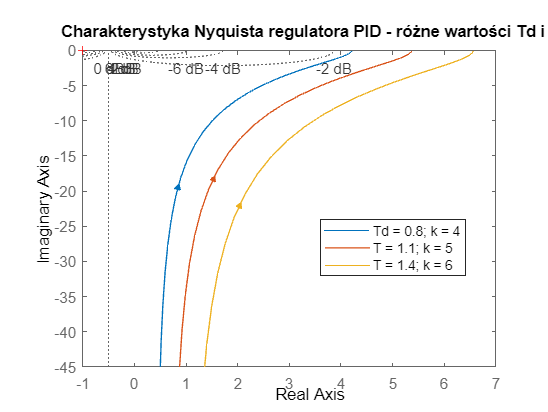


figure();
G1 = tf(licz1, mian);
G2 = tf(licz2, mian);
G3 = tf(licz3, mian);
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(G1, plotoptions)
hold on
nyquist(G2, plotoptions)
nyquist(G3, plotoptions)
hold off
grid on
title('Charakterystyka Nyquista regulatora PID - różne wartości Td i k')
legend('Td = 0.8; k = 4', 'T = 1.1; k = 5', 'T = 1.4; k = 6')
legend('Location', 'best')

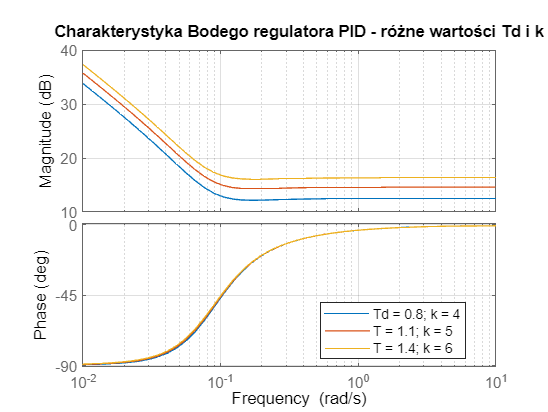


figure()
bode(licz1, mian)
hold on
bode(licz2, mian)
bode(licz3, mian)
hold off
grid on
title('Charakterystyka Bodego regulatora PID - różne wartości Td i k')
legend('Td = 0.8; k = 4', 'T = 1.1; k = 5', 'T = 1.4; k = 6')
legend('Location', 'best')

## Wnioski

Ćwiczenie pozwoliło na zapoznanie się z regulatorami PI, PD, PID, ich odpowiedziami skokowymi oraz charakterystykami Nyquista i Bodego, a także wpływem różnych sposobów przetwarzania uchybu na wyniki.